clear

## Define inputs:

platform_pose = [0 0 100 0.1 0.2 0.3]; %  x, y, z, psi, theta, phi

% enter distances read by time of flight sensors
sensor_distances = [4;
                     5;
                     6]; 

sensor_radius = 5; % radial distance from center point to sensor holes

% Enter how far away we want our platform to be offset from the detected surface
target_offset = 2;

To simplify calculations, all will be done with platform oriented at [0 0 0] with an axis-aligned orientation. Transformations will be applied afterwards based on the inputted platform pose.

% define the triangle
p = nsidedpoly(length(sensor_distances), 'Center', [0 0], 'SideLength', sensor_radius); 
% convert from polyshape to array
points = [p.Vertices ones(3,1)]; 

% transform the sensors bases to the measurement locations
sensed_points = points;
sensed_points(:,3) = sensed_points(:,3)+sensor_distances;

[normal_vector, ~,~,~,~] = findPlaneNormal(sensed_points(1,:),  sensed_points(2,:),  sensed_points(3,:))

normal_vector =     0.3714         0   -0.9285


% plot centroid
centroid = sum(sensed_points, 1)/3;
new_center = centroid + target_offset*normal_vector;

Now convert to the stewart base coordinate system:

target_coor = homogenousTransform(new_center, platform_pose, 'xyz')

target_coor =     1.5186
   -0.1729
  103.9218


%% WARNING: I am fairly certain this target angle is wrong. Or at the very least this is in a different order than our traditional rotation convention. This is why I hate euler angles >:(
target_angle = transformYPR(platform_pose(4), platform_pose(5), platform_pose(6), normal_vector)    % rad

target_angle = struct with fields:
      yaw: -0.4772
    pitch: -0.9079
     roll: -2.7973


#### Plot results:

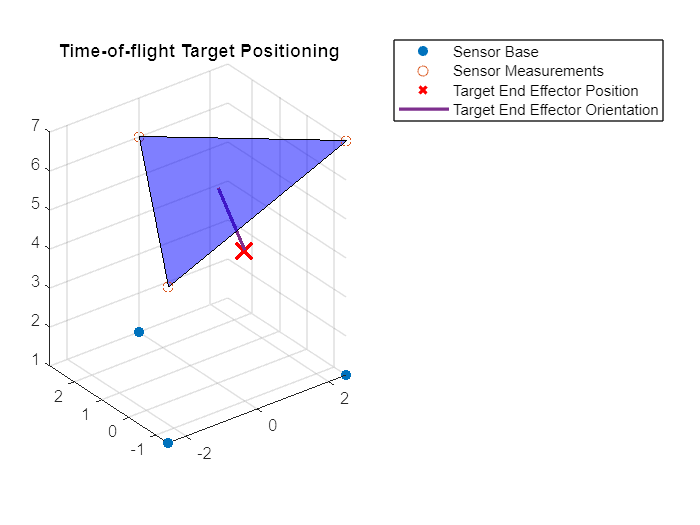

% plot triangle
scatter3(points(:,1), points(:,2), points(:,3), "filled", DisplayName="Sensor Base") % plot triangle
hold on
% plot laser measurement points
scatter3(sensed_points(:,1), sensed_points(:,2), sensed_points(:,3), "DisplayName", "Sensor Measurements")
patch(sensed_points(:,1),sensed_points(:,2),sensed_points(:,3), 'blue', "FaceAlpha", 0.5, "HandleVisibility", "Off")

% plot target line
scatter3(new_center(1), new_center(2), new_center(3), 200, "rX", 'LineWidth', 2, "DisplayName","Target End Effector Position")
plot3([centroid(1) new_center(1)], [centroid(2) new_center(2)], [centroid(3) new_center(3)], "LineWidth", 2, "DisplayName","Target End Effector Orientation")

legend()
title("Time-of-flight Target Positioning")
axis equal
hold off

function result = homogenousTransform(point, transform_values, sequence)
    R = eul2rotm(transform_values(4:6), sequence);
    T = [R  transform_values(1:3)';
         0 0 0 1];
    result = T * [point 1]';
    result = result(1:3);
end

function [normal_vector, A_coeff, B_coeff, C_coeff, D_coeff] = findPlaneNormal(p1, p2, p3)
    
    normal = cross(p1-p2, p1-p3);
    
    % Obtain the coefficients of the plane equation
    A_coeff = normal(1);
    B_coeff = normal(2);
    C_coeff = normal(3);
    D_coeff = -dot(normal, p1);
    
    % normalize normal vector
    normal_vector = [A_coeff B_coeff C_coeff] ./ norm([A_coeff B_coeff C_coeff]);

    % fprintf('Equation of the plane: %.2f*x + %.2f*y + %.2f*z + %.2f = 0\n', A_coeff, B_coeff, C_coeff, D_coeff);
end

function result = transformYPR(roll, pitch, yaw, V)
    
    % Step 1: Convert Euler angles (roll, pitch, yaw) to rotation matrix
    R = eul2rotm([roll, pitch, yaw]);  
    
    % Step 2: Take the transpose of the rotation matrix
    R_inv = R.';  % Transpose of the rotation matrix
    
    % Step 3: Apply inverse rotation transformation to the vector
    V_prime = R_inv * V';
    
    vector.x = V_prime(1);
    vector.y = V_prime(2);
    vector.z = V_prime(3);
    
    % Step 4: Convert to yaw pitch roll
    result.yaw = atan2(vector.y, vector.x);
    result.pitch = asin(vector.z);
    result.roll = atan2(vector.y, vector.z);
end